# The finite element method

***Note: ****For simplicity we only consider a 2D problem in divergence form and forgo the strict use of Sobolev space theory, needed for the rigorous treatment of the FEM. A comprehensive mathematical  formulation can instead be found in the accompanying paper, for example.*

Let $\Omega \in \mathbf{R}^2$ be a domain with $\partial \Omega = \Gamma_1 \cup \Gamma_2, \ \Gamma_1^{\circ} \cap \Gamma_2^{\circ} = \emptyset$. Further let $f :\Omega \to \mathbf{R}$, $g:\Gamma_1 \to \mathbf{R}$, $h:\Gamma_2 \to \mathbf{R}$ be continuous  and let $a:\Omega \to \mathbf{R}$ be continuous, bounded and differentiable mappings. We seek to find a twice continuously differentiable mapping $u: \bar{\Omega} \to \mathbf{R}$, which solves the strong form of the following partial differential equation (PDE).


$$
div \left ( a \, grad\, u \right ) = \nabla \cdot \left ( a \nabla u \right )  = -f, \text{in} \ \Omega, \\
u_{\vert \Gamma_1} = g, \text{ on } \Gamma_1, \\
\frac{\partial u}{\partial n}{\vert_{\Gamma_2} = h, \text{ on } \Gamma_2. 

$$


Here, Dirichlet boundary conditions (the first type) and Neumann boundary conditions (the second type) are considered.

Instead of solving the strong form of the PDE, we seek to solve the so called weak form of the PDE which is obtained by multiplying above equation with so called test functions $\varphi$ and integrating it over the whole domain.  In other words, find $u
$, such that for all test functions $\varphi$


$$\int \limits_{\Omega} \nabla \cdot \left ( a \nabla u \right ) \varphi \ \mathrm{dA} = - \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


By exploiting $\nabla \cdot \left ( u v\right) = \nabla u \cdot v + u \nabla \cdot v$ and Gauss' divergence theorem we have


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\partial \Omega} \varphi a \nabla u \cdot \vec{n} \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


Where $\vec{n}$ denotes the outer normal to $\Omega$. Taking into account only those test functions $\varphi$ that are $0$ on $\Gamma_1$ and inserting the identity given by the Neumann boundary conditions, we end up with


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\Gamma_2} a \varphi  h \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}, \text{ for all }\varphi,\text{ with }\varphi=0 \text{ on }\Gamma_1,$$


or, by using the standard $L^2$ inner product notation:


$$\langle \nabla u, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}.$$


Discretization is performed with the Galerkin approach. There, the same  finite dimensional vector space $V$ is chosen as ansatz space for the test and trail functions. Thus, the problem transforms to:

*Find  *$u_h \in V$*with *$u_{h \vert_{\Gamma1}} =g$* on *$\Gamma_1$*, which solves *


$$\langle \nabla u_h, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}$$
 

*for all *$v \in V.$

Representing all participating functions in terms of a basis set $\lbrace \varphi_k \rbrace_{k=1, \ldots, n}$, i.e., $u_h = \sum \limits_{k=1}^n \alpha_k \varphi_k$, the following can be obtained:


$$\langle \sum \limits_{k=1}^n \alpha_k \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n \\
\Leftrightarrow \sum \limits_{k=1}^n \alpha_k \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n,$$


where the coefficients $\alpha_k$ are the only unknowns. Therefore the above can be written as a system of linear equations of the form


$$C a = b_{\text{force}} + b_{\text{boundary}},$$


with 


$$C = \pmatrix{\langle \nabla \varphi_1, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_1, \nabla \varphi_n \rangle_{\Omega} \cr \vdots & \vdots &\vdots \cr \langle \nabla \varphi_n, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_n, \nabla \varphi_n \rangle_{\Omega}}, a= \pmatrix{\alpha_1 \cr \vdots \cr \alpha_n}, b_{\text{force}} = \pmatrix{\langle f, \varphi_1 \rangle_{\Omega} \cr \vdots \cr \langle f, \varphi_n \rangle_{\Omega} }, \text{ and } b_{\text{boundary}} = \pmatrix{\langle h, \varphi_1 \rangle_{\Gamma_2} \cr \vdots \cr \langle h, \varphi_n \rangle_{\Gamma_2}}.$$


The matrix $C$is denoted as the stiffness matrix, and the vectors $b_{\text{force}},\ b_{\text{boundary}}$ are the load vectors.

# Space and geometry discretization

***Note: ****We restrict ourselves to linear finite elements on triangles whose degrees of freedom are the vertices of said triangles. Of course other degrees of freedom can be chosen and higher order polynomials can be used.*

The finite dimensional vector space $V$ is usually constructed over a mesh. Such a mesh generally consists of simple, non overlapping, geometrical forms, such as triangles, and covers all of $\Omega
$. Then, $V$ consists of functions whose restriction on each element of the mesh ($\Omega_i$) is a polynomial, and which are sufficiently smooth on the whole domain $\Omega$. The simplest possible family of such functions are those, which are affine linear on a triangle $\Omega_i$ and continuous on $\Omega$. They are chosen as test and trail functions. 


$$\varphi_{\vert_{\Omega_i}} : \Omega_i \to \mathbf{R},\\
\varphi (x,y) = a_{\Omega_i}+ b_{\Omega_i}x + c_{\Omega_i}y$$


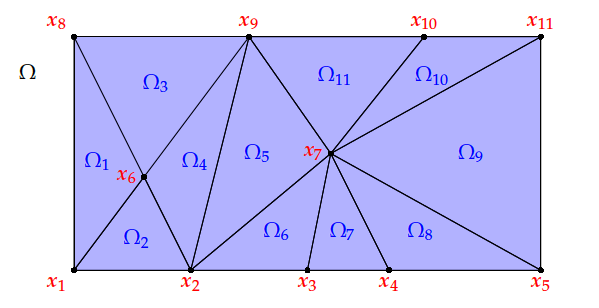

The functions $\varphi$ are uniquely defined once their values at the vertices of each triangle are known, making the vertices the degrees of freedom (DOFs). Let $\varphi_k$ be the k-th basis function of V, then 


$$\varphi_k (x_l, y_l) =0, \text{ for }l\neq k \\
\varphi_k (x_k, y_k) =1.$$


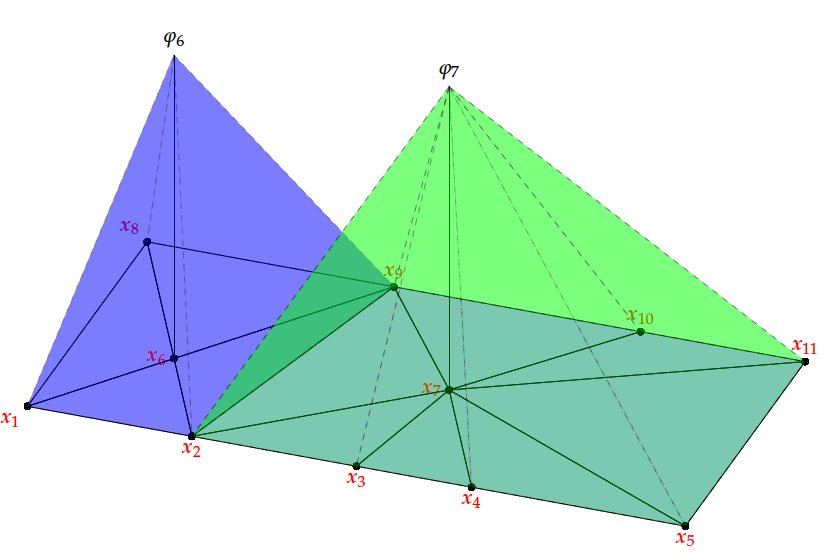

Thus, the entries of the stiffness matrix $C$can be computed on each triangle, since


$$\sum \limits_{k=1}^n \alpha_k \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n\\
\Leftrightarrow  \sum \limits_{k=1}^n \alpha_k \sum \limits_{\Omega_i \in \mathcal{T}} \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega_i} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n \\
\Rightarrow c_{kl} = \sum \limits_{\Omega_i \in \mathcal{T}} \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega_i}$$


There are only 3 basis functions not zero on a single triangle, thus one can compute the entries $c^k_{ij} =  \langle \nabla \varphi_{k_j}, \nabla \varphi_{k_i} \rangle_{\Omega_k}$. So on each single triangle a $3 \times 3$ local stiffness matrix is computed and then sorted into the global stiffness matrix. This procedure is called assembling. The management of this process if done via a DOF manager, who keeps track of the local and global coordinates.

%Construction of a mesh:
%The domain Omega = [0,1] x [0,1] shall be discretized into triangles. A possible way is the following, with an element and ad a coordinate vector.

% The coordinate matrix of the mesh
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

% The element matrix of the mesh
elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];
% Coordinates of the triangle number 1
co(elem(1,:),:)

ans =          0         0
    0.3333         0
         0    0.3333


# Local stiffness matrix computation

The computation of the entries of the local stiffness matrix is done by using the mapping of a triangle $\Omega_1$ onto the reference unit triangle.

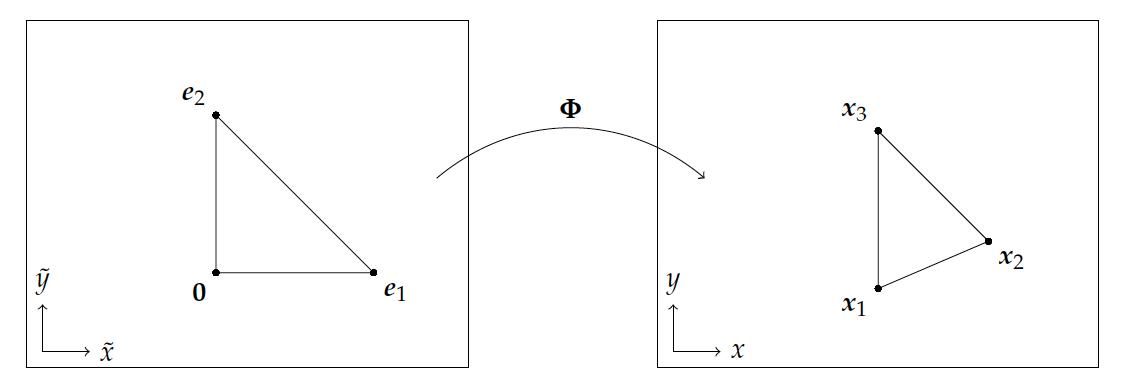

The mapping reads


$$\Phi_{k}\left(\tilde{x}\right)=\underbrace{\left (x_{k}^{2}-x_{k}^{1},  x_{k}^{3}-x_{k}^{1} \right )}\limits_{D_k :=} \tilde{x} +x_{k}^{1}$$


Using this mapping we can perform the computation of the integrals in the reference system. To this end we define


$$\tilde{\varphi}_{i}:=\varphi_{i}\circ \Phi_{k} \text{ and } \tilde{\nabla}:=\nabla_{\tilde{x}}.$$


And for the matrix entries $c_{ij}^k$ we have


$$	c_{ij}^{k}
	=
	\int\limits_{\Omega_{k}} \nabla^{\top} \varphi_{i}(x)\nabla \varphi_{j}(x)\,d x\\
	=
	\int\limits_{\Omega_{k}} \left(\nabla \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)^{\top}\left(\nabla \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\,d x\\
	=
	\int\limits_{\Omega_{k}} \left(D_{k}^{-\top}\tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\left(D_{k}^{-\top}\tilde{\nabla} \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\right)\,d x\\
	=
	\int\limits_{\Omega_{k}} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\Phi_{k}^{-1}\left(x\right)\right)\underbrace{D_{k}^{-1}D_{k}^{-\top}}\limits_{A_{k}}\tilde{\nabla} \tilde{\varphi}_{j}\left(\Phi_{k}^{-1}\left(x\right)\right)\,d x\\
	=
	\int\limits_{\Delta} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\tilde{x}\right)A_{k}\tilde{\nabla} \tilde{\varphi}_{j}\left(\tilde{x}\right)\left|\text{det}\, D_{k}\right|\,d \tilde{x}\\
	=
	\left|\text{det}\, D_{k}\right| \int\limits_{\Delta} \tilde{\nabla}^{\top} \tilde{\varphi}_{i}\left(\tilde{x}\right)A_{k}\tilde{\nabla} \tilde{\varphi}_{j}\left(\tilde{x}\right)\,d \tilde{x}.$$


Now let's try to assemble the per element stiffness matrix according to above derived formula:

% We need the mesh  
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% The size of the stiffness matrix
n=size(co,1);
m=size(elem,1);

C=zeros(n,n);

%And now we loop over all triangles
for k=1:m 
    k1 = elem(k,1);
    k2 = elem(k,2);
    k3 = elem(k,3);

    nk1 = co(k1,:)';
    nk2 = co(k2,:)';
    nk3 = co(k3,:)';

    Dk = [ nk2-nk1, nk3-nk1 ];

    Dkinv = inv(Dk);

    gradvk1 = Dkinv'*[-1;-1];
    gradvk2 = Dkinv'*[ 1; 0];
    gradvk3 = Dkinv'*[ 0; 1];

    Cloc = det(Dk)/2*[ dot(gradvk1,gradvk1), dot(gradvk1,gradvk2), dot(gradvk1,gradvk3); ...
                       dot(gradvk2,gradvk1), dot(gradvk2,gradvk2), dot(gradvk2,gradvk3); ...
                       dot(gradvk3,gradvk1), dot(gradvk3,gradvk2), dot(gradvk3,gradvk3); ]

    C([k1,k2,k3],[k1,k2,k3])=C([k1,k2,k3],[k1,k2,k3])+Cloc;
end

Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


Cloc =     1.0000   -0.5000   -0.5000
   -0.5000    0.5000         0
   -0.5000         0    0.5000


Cloc =     0.5000   -0.5000         0
   -0.5000    1.0000   -0.5000
         0   -0.5000    0.5000


C

C =     1.0000   -0.5000         0         0   -0.5000         0         0         0         0         0         0         0         0         0         0         0
   -0.5000    2.0000   -0.5000         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0
         0   -0.5000    2.0000   -0.5000         0         0   -1.0000         0         0         0         0         0         0         0         0         0
         0         0   -0.5000    1.0000         0         0         0   -0.5000         0         0         0         0         0         0         0         0
   -0.5000         0         0         0    2.0000   -1.0000         0         0   -0.5000         0         0         0         0         0         0         0
         0   -1.0000         0         0   -1.0000    4.0000   -1.0000         0         0   -1.0000         0         0         0         0         0         0
         0         0   -1.0000

This code can be improved by using Matlab's repelem, repmat and reshape functions to efficiently perform computations with vectors

doc repmat
doc repelem
doc reshape

%The Mesh:
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

n=size(co,1);
m=size(elem,1);

C=zeros(n,n);

for k=1:m
%     k1 = elem(k,1);
%     k2 = elem(k,2);
%     k3 = elem(k,3);
% 
%     nk1 = co(k1,:)';
%     nk2 = co(k2,:)';
%     nk3 = co(k3,:)';
% 
%     Dk = [ nk2-nk1, nk3-nk1 ];
% 
%     Dkinv = inv(Dk);
% 
%     gradvk1 = Dkinv'*[-1;-1];
%     gradvk2 = Dkinv'*[ 1; 0];
%     gradvk3 = Dkinv'*[ 0; 1];
% 
%     Cloc = det(Dk)/2*[ dot(gradvk1,gradvk1), dot(gradvk1,gradvk2), dot(gradvk1,gradvk3); ...
%                        dot(gradvk2,gradvk1), dot(gradvk2,gradvk2), dot(gradvk2,gradvk3); ...
%                        dot(gradvk3,gradvk1), dot(gradvk3,gradvk2), dot(gradvk3,gradvk3); ];
% 
%     C([k1,k2,k3],[k1,k2,k3])=C([k1,k2,k3],[k1,k2,k3])+Cloc;


    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];
    %repelem(gradv',3,1)
    %repmat(gradv',3,1)

    Cloc=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    C(idx,idx)=C(idx,idx)+Cloc;
end

ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


ans =          0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0
         0   -3.0000
    3.0000    3.0000
   -3.0000         0


C

C =     0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5000    2.0000   -0.5000         0   -0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0
         0   -0.5000    2.0000   -0.5000         0   -0.5000   -0.5000         0         0         0         0         0         0         0         0         0
         0         0   -0.5000    1.5000         0         0   -0.5000   -0.5000         0         0         0         0         0         0         0         0
         0   -0.5000         0         0    1.5000   -1.0000         0         0         0         0         0         0         0         0         0         0
         0   -0.5000   -0.5000         0   -1.0000    4.0000   -1.0000         0   -0.5000   -0.5000         0         0         0         0         0         0
         0         0   -0.5000

We will stick with this code for a while. Let us now include boundary conditions:

- First we need to define the regions where the boundary condtions are applied, this can be something like:

% Our mesh
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% The degrees of freedom are exactly the vertices
DOF=1:size(co,1);

%% Dirichlet BCs are declared pointwise
diri = 1:4;
alpha_diri = 1;

DOF=setdiff(DOF,diri);

%% Neumann BCs are declared as edges
neumann = [  4, 8; ...
             8,12; ...
            12,16];

- Assembling the stiffness matrix is just like it was before:

%% The stiffness matrix
n=size(co,1);
m=size(elem,1);

C=zeros(n,n);

for k=1:m
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];

    Cloc=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    C(idx,idx)=C(idx,idx)+Cloc;
end

- We will also consider a right hand side (the function force is declared at the end)

%% RHS
b_force=zeros(n,1);

for k=1:m
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];
    
    fk = force((co(idx(1),:)+co(idx(2),:)+co(idx(3),:))/3);

    b_force(idx)=b_force(idx)+fk*det(Dk)*1/6;
end



- In a similar fashion Neumann boundary conditions can be assembled (the function neumannBC is declared at the end)

%% Neumann BCs
b_neu=zeros(n,1);
for k = 1:size(neumann,1)
    
   idx = neumann(k,:);
   
   d = co(idx(2),:) - co(idx(1),:);
   
   d_norm = norm(d);

   hk = neumannBC((co(idx(2),:)+co(idx(1),:))/2);
   
   b_neu(idx)=b_neu(idx)+hk*d_norm/2;
    
end

- Dirichlet boundary is accounted for with DOF management


%% Account for Dirichlet BCs
alpha=zeros(n,1);
alpha(diri)=alpha_diri;

b_diri = -C*alpha;
%% The complete RHS
b=b_force+b_neu+b_diri;


%% Solving the linear system for the remaining DOFs
alpha(DOF)=C(DOF,DOF)\b(DOF);

alpha

alpha =     1.0000
    1.0000
    1.0000
    1.0000
    1.4568
    1.4820
    1.5705
    1.7715
    1.7520
    1.7896


Now that we understood how this works let us focus on code design. In oFEM we like checks, and we like functions (which will become methods, eventually). Most of all we like nice comments. So let us tweak the above and rewrite it, such that we can call something like this:

[co,elem,u_ref,opt]=poison_ref;

u=poison_my(co,elem,opt);

sum(abs(u-u_ref))

ans = 1.5543e-14

So we need to write two functions poison_ref and poison. The first function is simply all we did before wrapped in a function:

function [co,elem,u,opt]=poison_ref
% The mesh
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% DOFs
DOF=1:size(co,1);

%% Declare Dirichlet boundary
diri = 1:4;
alpha_diri = 1;
opt.dirichlet=diri;
opt.g=alpha_diri;

DOF=setdiff(DOF,diri);

%% Declare Neuman boundary
neumann = [  4, 8; ...
             8,12; ...
            12,16];
opt.neumann=neumann;

%% Assamble stiffness matrix
n=size(co,1);
m=size(elem,1);

A=zeros(n,n);

for k=1:m
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];

    Cloc=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    A(idx,idx)=A(idx,idx)+Cloc;
end


%% RHS
b_force=zeros(n,1);
fn=zeros(m,1);

for k=1:m
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];
    
    fk = force((co(idx(1),:)+co(idx(2),:)+co(idx(3),:))/3);
    fn(k)=fk;

    b_force(idx)=b_force(idx)+fk*det(Dk)*1/6;
end
opt.f=fn;

%% Neumann BCs
b_neu=zeros(n,1);
hn=zeros(size(neumann,1),1);

for k = 1:size(neumann,1)
    
   idx = neumann(k,:);
   
   d = co(idx(2),:) - co(idx(1),:);
   
   d_norm = norm(d);

   hk = neumannBC((co(idx(2),:)+co(idx(1),:))/2);
   hn(k)=hk;
   
   b_neu(idx)=b_neu(idx)+hk*d_norm/2;
    
end
opt.h=hn;

% Include Dirichlet BCs
u=zeros(n,1);
u(diri)=alpha_diri;

b_diri = -A*u;


b=b_force+b_neu+b_diri;

% Solve linear system
u(DOF)=A(DOF,DOF)\b(DOF);

end


The second function is the nicer version, with checks, comments and all the stuff needed for portable Matlab code, just the way we like it in oFEM:


function u=poison_my(co,elem,varargin)
%POISON solves Poison equation
%
% u=POISON(co,elem) solves the Laplace equation on the domain Omega
% represented by the pair co and elem assuming homogenous Dirichlet
% boundary. co is a Ncx2 matrix containing per row the coordinates off a
% single node of the mesh. elem is a Nex3 matrix containing per row
% indices of the nodes. This triple describes which nodes are used to build
% up the respective element. The coordinate vector u of the approximate
% solution is returned.
%
% u=POISON(co,elem,opt) additionally expects a structure describing the
% domain in more detail.
% If the field dirichlet is present in the structure
% the function takes it as the Dirichlet boundary. opt.dirichlet is
% expected to be a vector of length Nd of indices into the co matrix. In
% this case if a field g is present in opt, expected to be either a
% function handle or a numeric vector the same length as opt.dirichlet, it
% is taken as the boundary data. If g is a function handle it is expected
% to take a single argument x which is a Npx2 matrix with a coordinate
% per row describing the points where g should be evaluated and return a
% single vector of length Np with function values at x. If g is not present
% homogenous data is assumed.
% The same way, if a field neumann is found it is assumed to represent the
% Neumann part of the boundary. opt.neumann is expected to be a Nnx2 matrix
% containing per row the indices of the nodes the boundary segment is build
% up from. As for Dirichlet data a field h is sought for, again, either
% being a function handle or a vector of length Nn. The function is assumed
% to receive two arguments, the first one, x, being the point of evaluation
% and the second one, n, being the outer normal to the boundary at this
% point. Moreover, a scalar value is assumed to be returned per row i of x
% representing the function evaluation at x(i,:) and n(i,:).
% A field f, either being a function handle or a vector of length Ne,
% describes the right-hand side. The function form is expected to receive a
% matrix x of points f is to be evaluated and return a vector of point
% evaluations.
%

opt=[];
if nargin==3
    opt=varargin{1};
end

%% matrices and right hand side
Nc=size(co,1);
Ne=size(elem,1);
A=sparse(Nc,Nc); % stiffness matrix
% b=sparse(Nc, 1); % right-hand side
u=zeros (Nc, 1);

%% determine DOFs
DOF=1:Nc;

%% Dirichlet boundary
diri=[];
Nd=0;
if isfield(opt,'dirichlet')
    if ~isvector(opt.dirichlet)
        error('poison:argChk','opt.dirichlet is expected to be a vector');
    end
    diri=opt.dirichlet;
    if iscolumn(diri); diri=diri'; end
    Nd=size(diri,1);
end

if isfield(opt,'g')
    if isnumeric(opt.g)
        % check for length consistency
        if isvector(opt.g) && numel(opt.g)==Nd
            g=opt.g;
        else
            error('poison:argChk','opt.g must be a vector of length %d',Nd);
        end
    elseif isa(opt.g,'function_handle')
        g=opt.g(co(diri,:));
    else
        error('poison:argChk','opt.g must be either a vector or a function handle');
    end
else
    g=zeros(Nd,1);
end

DOF=setdiff(DOF,diri);

%% Neumann boundary
neu=[];
Nn=0;
if isfield(opt,'neumann')
    if ~(ismatrix(opt.neumann) && size(opt.neumann,2)==2)
        error('poison:argChk','opt.neumann is expected to be a matrix with two columns');
    end
    neu=opt.neumann;
    Nn=size(neu,1);
end

if isfield(opt,'h')
    if isnumeric(opt.h)
        % check for length consistency
        if isvector(opt.h) && numel(opt.h)==Nn
            h=opt.h;
        else
            error('poison:argChk','opt.h must be a vector of length %d',Nn);
        end
    elseif isa(opt.g,'function_handle')
        x1=co(neu(:,1),:);
        x2=co(neu(:,2),:);
        h=opt.h((x1+x2)/2,(x2-x1)./sqrt(dot(x2-x1,x2-x1,2)));
    else
        error('poison:argChk','opt.h must be either a vector or a function handle');
    end
else
    h=zeros(Nn,1);
end


%% assemble stiffness matrix
for k=1:Ne
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];

    A_elem=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    A(idx,idx)=A(idx,idx)+A_elem;
end


%% assemble right-hand side
b_f=zeros(Nc,1);

for k=1:Ne
    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];
    
    fk = force((co(idx(1),:)+co(idx(2),:)+co(idx(3),:))/3);

    b_f(idx)=b_f(idx)+fk*det(Dk)*1/6;
end

%% assemble Neumann boundary data
b_n=zeros(Nc,1);

for k = 1:Nn
    idx = neu(k,:);

    d = co(idx(2),:) - co(idx(1),:);

    d_norm = norm(d);

    b_n(idx)=b_n(idx)+h(k)*d_norm/2;
end

%% correct for Dirichlet boundary data
u(diri)=g;
b_d=-A*u;

%% whole right-hand side
b=b_d+b_f+b_n;



%% solve resulting linear system
u(DOF)=A(DOF,DOF)\b(DOF);

end


function y=force(x)
    y=ones(size(x,1),1);
end

function y=neumannBC(x)
    y=ones(size(x,1),1);
end

